% Clear command window, workspace variables, and close all figures
clear; clc; close all;

% Set the path to the folder containing the layer data
layerfolder = 'data/Capas_Colombia_30S/';

% Read in the layer data from the specified folder
Dimensions = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 10.571986 seconds.



% Generate initial point for niche generation using a virtual species method
InfoInitialPoint = InitialPoint(Dimensions,'coeff');

Elapsed time is 16.930462 seconds.


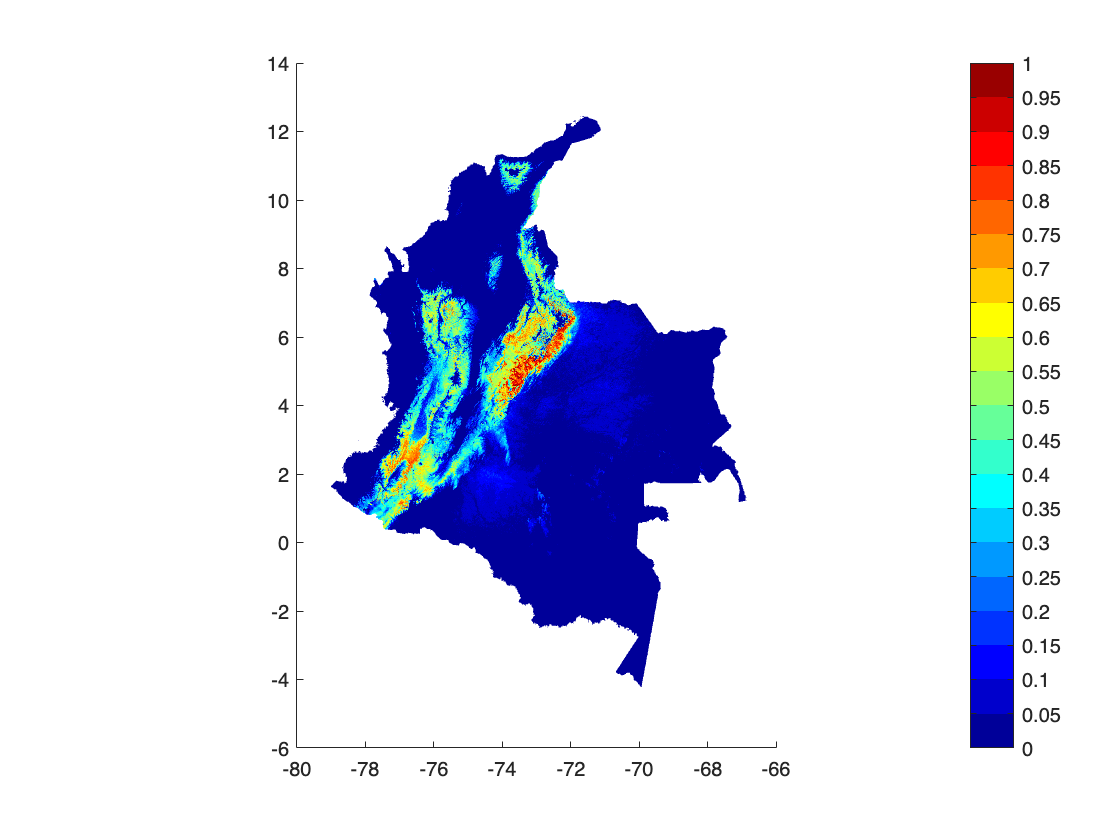

Elapsed time is 0.775560 seconds.


% Generate the niche map using niche generation algorithm with the initial point
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true);

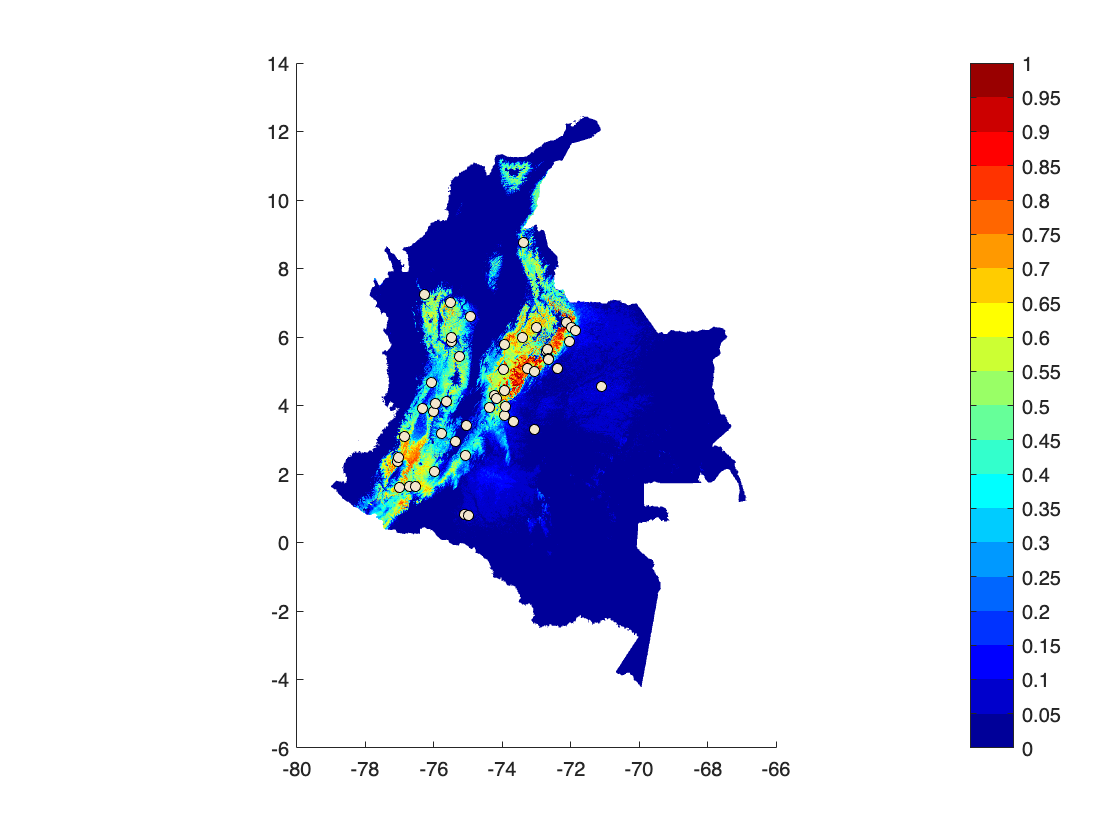

% Sample virtual species using the generated niche map
T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 50, -1, true, 'GenSP', true, true);